Compute the rankability of an unweighted graph read from a file.

% Add the paths needed for this tutorial
addpath('exhaustive')
addpath('lp')
addpath('../linspecer')

D = csvread('data/unweighted1.csv');
disp('The size of the D matrix is:')

The size of the D matrix is:


disp(size(D))

     6     6



D

D =      0     1     1     0     0     1
     0     0     1     1     0     0
     0     1     0     0     0     0
     1     0     0     0     0     1
     1     0     0     0     0     0
     0     1     1     0     1     0


[k,p,P,stats] = rankability_exhaustive(D,'transform',true);

fprintf('k=%d, p=%d, r=%f, rtransformed=%f\n',k,p,stats.r,stats.rtransformed)

k=9, p=12, r=0.990000, rtransformed=0.063451


Visualize the results

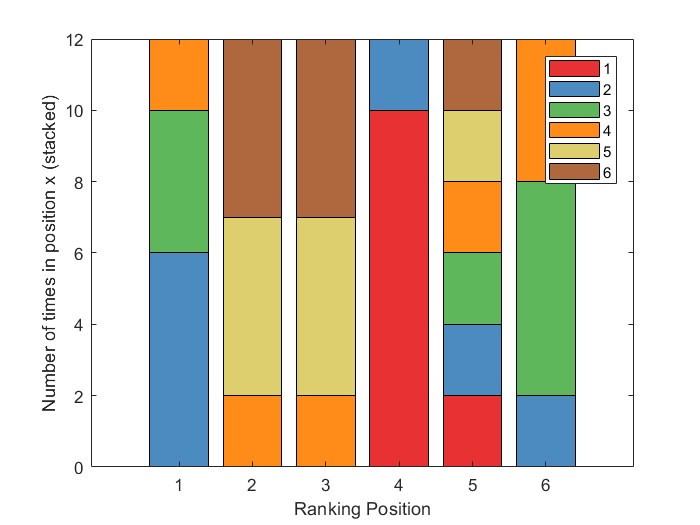

counts=hist(P',1:size(D,1));
H=bar(counts,'stacked');
labels = {'1','2','3','4','5','6'};
legend(labels)
xlabel('Ranking Position')
ylabel('Number of times in position x (stacked)');

myC = linspecer(size(D,1));
for i=1:size(D,1)
  set(H(i),'facecolor',myC(i,:))
end


% Ranking matrix R; R(i,j)=percentage of ranking vectors in P that have
% item i in jth rank position
n=size(D,1);
R=zeros(n,n);
for i=1:n
    for j=1:p
        R(P(i,j),i)=R(P(i,j),i)+1;
    end
end
R=R./p

R =          0    0.5000    0.3333    0.1667         0         0
         0         0         0    0.1667    0.4167    0.4167
         0         0         0    0.1667    0.4167    0.4167
    0.8333    0.1667         0         0         0         0
    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
         0    0.1667    0.5000    0.3333         0         0


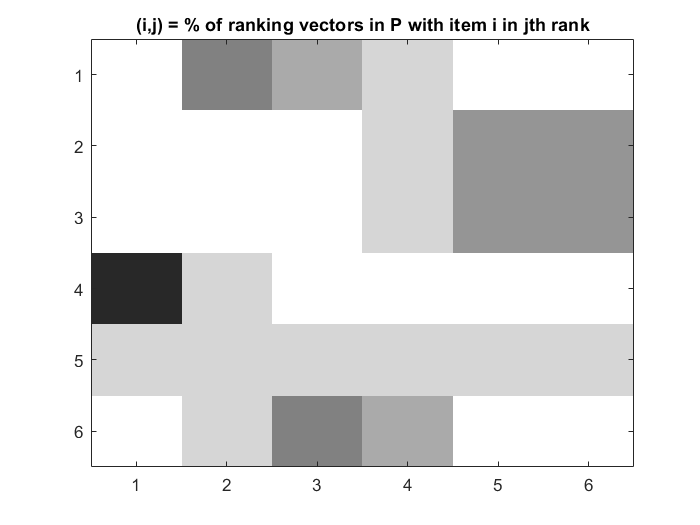


imagesc(1-R)
ax = gca;
%ax.Visible = 'off'
colormap(gray)
caxis([0 1])
title('(i,j) = % of ranking vectors in P with item i in jth rank')
xticklabels(labels);
yticklabels(labels);

Find k using LP method and approximate p.

[k,p,X,Y] = rankability_lp(D);
fprintf('k=%d, p=%d\n',k,p)

k=9.000000e+00, p=14


Compute the rankability of a weighted graph read from a file

D = csvread('data/weighted1.csv');
disp(['The size of the D matrix is:'])

The size of the D matrix is:


disp(size(D))

     8     8



D

D =      0     0    79    82    74     0    61    79
     0     0    79    89    89    74     0     0
    21    21     0    68    63    68     0    66
    18    11    32     0    87    63    61    76
    26    11    37    13     0     0    55     0
     0    26    32    37     0     0    74    76
    39     0    34    39    45    26     0    84
    21    16    34     0    21    24    16     0


[k,p,P,stats] = rankability_exhaustive(D,'transform',true);

fprintf('k=%d, p=%d, r=%f, rtransformed=%f\n',k,p,stats.r,stats.rtransformed)

k=1523, p=2, r=0.999970, rtransformed=0.194499


perm = P(:,1);
Doptimal = D(perm,perm)

Doptimal =      0     0    79    89    74     0     0    89
     0     0    79    82     0    61    79    74
    21    21     0    68    68     0    66    63
    11    18    32     0    63    61    76    87
    26     0    32    37     0    74    76     0
     0    39    34    39    26     0    84    45
    16    21    34     0    24    16     0    21
    11    26    37    13     0    55     0     0


Dperfect = triu(max(max(D))*ones(size(D,1),size(D,1)),1)

Dperfect =      0    89    89    89    89    89    89    89
     0     0    89    89    89    89    89    89
     0     0     0    89    89    89    89    89
     0     0     0     0    89    89    89    89
     0     0     0     0     0    89    89    89
     0     0     0     0     0     0    89    89
     0     0     0     0     0     0     0    89
     0     0     0     0     0     0     0     0


Run LP on a weighted example.

[k,p,X,Y] = rankability_lp(D);
fprintf('k=%d, p=%d\n',k,p)

k=1.523000e+03, p=2


For larger graphs and datasets, the parallel implementation can be called:

[k,p,P,stats] = rankability_exhaustive_parallel(D,10,'transform',true);

fprintf('k=%d, p=%d, r=%f, rtransformed=%f\n',k,p,stats.r,stats.rtransformed);

k=1523, p=2, r=0.999970, rtransformed=0.194499


Standard examples from the paper

Strong Dominance

D=[0 1 1 1 1 1 1 1; 0 0 1 1 1 1 1 1; 0 0 0 1 1 1 1 1; 0 0 0 0 1 1 1 1; 0 0 0 0 0 1 1 1; 0 0 0 0 0 0 1 1; ; 0 0 0 0 0 0 0 1; ; 0 0 0 0 0 0 0 0];
[k,p,P,stats] = rankability_exhaustive(D,'transform',true);
fprintf('k=%d, p=%d, r=%f, rtransformed=%f\n',k,p,stats.r,stats.rtransformed);

k=0, p=1, r=1.000000, rtransformed=1.000000


Fully Connected

D=ones(7,7);
for i = 1:size(D,1)
    D(i,i) = 0;
end
[k,p,P,stats] = rankability_exhaustive(D,'transform',true);
fprintf('k=%d, p=%d, r=%f, rtransformed=%f\n',k,p,stats.r,stats.rtransformed);

k=21, p=5040, r=0.000000, rtransformed=0.000000


Random graphs

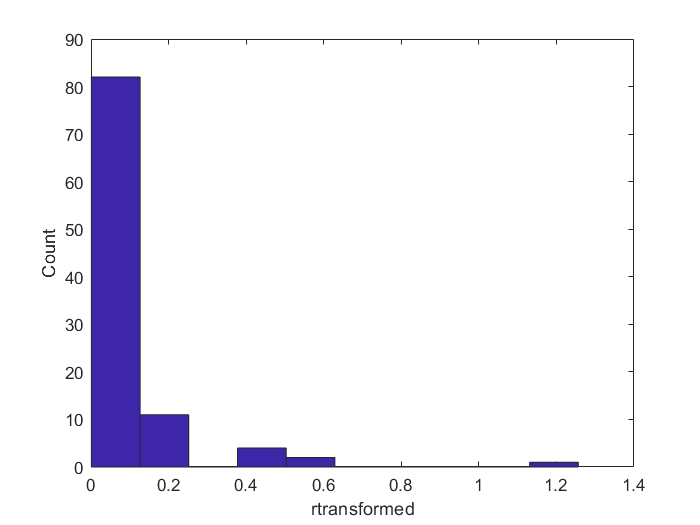

ntimes = 100;
rtransformed = zeros(1,ntimes);
for j = 1:ntimes
    D=round(rand(7,7));
    for i = 1:size(D,1)
        D(i,i) = 0;
    end
    [k,p,P,stats] = rankability_exhaustive(D,'transform',true);
    rtransformed(j) = stats.rtransformed;
end
hist(rtransformed);
ylabel('Count')
xlabel('rtransformed')

Weak Dominance

D=zeros(7,7);
for i = 1:size(D,1)-1
    D(i,i+1) = 1;
end
[k,p,P,stats] = rankability_exhaustive(D,'transform',true);
fprintf('k=%d, p=%d, r=%f, rtransformed=%f\n',k,p,stats.r,stats.rtransformed);

k=15, p=1, r=0.999858, rtransformed=0.285714
